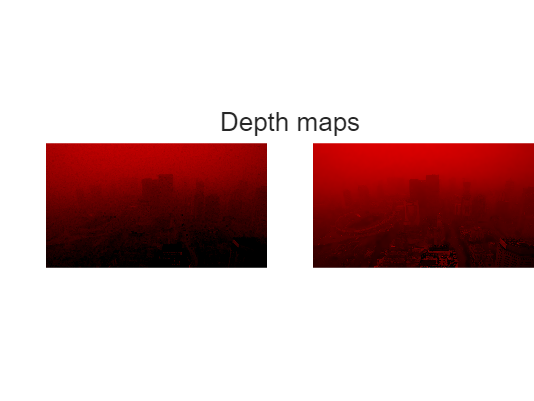

close all;clear;clc;

inputImagePath = 'inputImgs/haze.jpg';
I = imread(inputImagePath);
r = 15;
beta = 1.0;

%----- Parameters for Guided Image Filtering -----
gimfiltR = 60;
eps = 10^-3;

tic;
[dR, dP] = calVSMap(I, r);
refineDR = fastguidedfilter_color(double(I)/255, dP, r, eps, r/4);

tR = exp(-beta*refineDR);
tP = exp(-beta*dP);

hsvDepthMap = cat(3, dR, zeros(size(dR)), zeros(size(dR)));
imwrite(hsvDepthMap, 'res/originalDepthMap.png');

hsvRefinedDepthMap = cat(3, refineDR, zeros(size(refineDR)), zeros(size(refineDR)));
imwrite(hsvRefinedDepthMap, 'res/refineDepthMap.png');

figure;
t1 = tiledlayout(1, 2);
t1.Title.String = "Depth maps";
t1.Padding = "tight";
t1.TileSpacing = "tight";

nexttile;
imshow(hsvDepthMap);

nexttile;
imshow(hsvRefinedDepthMap);

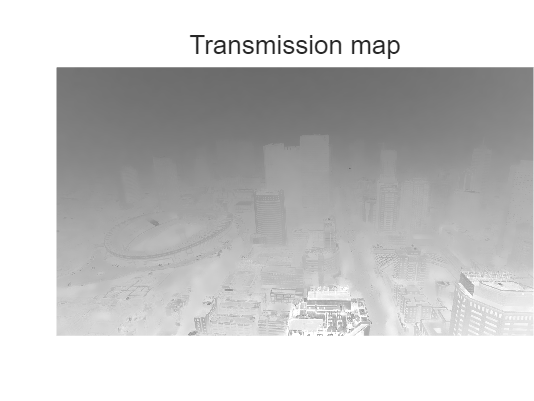


imwrite(tR, 'res/transmission.png');

figure;
t1 = tiledlayout(1, 1);
t1.Title.String = "Transmission map";
t1.Padding = "tight";
t1.TileSpacing = "tight";

nexttile;
imshow(tR);

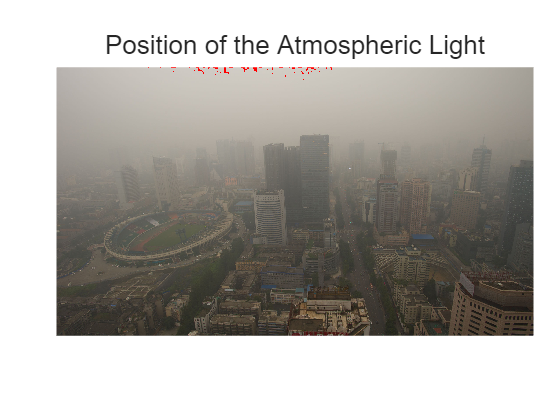


a = estA(I, dR);

t0 = 0.05;
t1 = 1;
I = double(I)/255;
[h, w, c] = size(I);
J = zeros(h,w,c);
J(:,:,1) = I(:,:,1)-a(1);
J(:,:,2) = I(:,:,2)-a(2);
J(:,:,3) = I(:,:,3)-a(3);

t = tR;
[th, tw] = size(t);
for y=1:th
    for x=1:tw
        if t(y,x)<t0
            t(y,x)=t0;
        end
    end
end

for y=1:th
    for x=1:tw
        if t(y,x)>t1
            t(y,x)=t1;
        end
    end
end

J(:,:,1) = J(:,:,1)./t;
J(:,:,2) = J(:,:,2)./t;
J(:,:,3) = J(:,:,3)./t;

J(:,:,1) = J(:,:,1)+a(1);
J(:,:,2) = J(:,:,2)+a(2);
J(:,:,3) = J(:,:,3)+a(3);

toc;

Elapsed time is 8.112025 seconds.


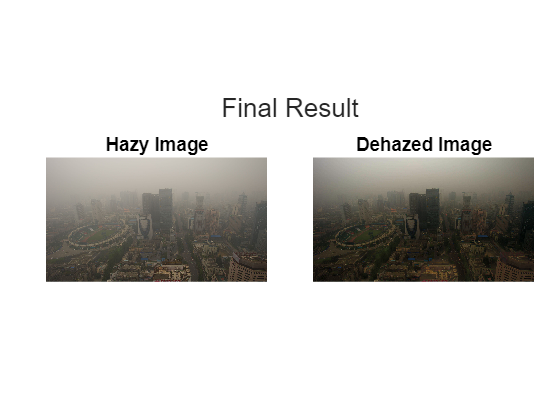

figure;
t1 = tiledlayout(1, 2);
t1.Title.String = "Final Result";
t1.Padding = "tight";
t1.TileSpacing = "tight";

nexttile();
imshow(I);
title("Hazy Image");

nexttile;
imshow(J);
title("Dehazed Image");


saveName = ['res/' num2str(r) '_beta' num2str(beta) '.png'];
imwrite(J, saveName);

function [ A ] = estA( img, Jdark, isShowImg)

if nargin < 3
    isShowImg = 1;
end


[h,w,~] = size(img);
if isinteger(img)
    img = double(img)/255;
end

n_bright = ceil(0.001*h*w);
[~,Loc] = sort(Jdark(:));

Ics = reshape(img, h*w, 1, 3);
ix = img;

Acand = zeros(n_bright,1,3);
Amag = zeros(n_bright,1);

for i = 1:n_bright
    x = Loc(h*w+1-i);
    ix(mod(x,h)+1, floor(x/h)+1, 1) = 1;
    ix(mod(x,h)+1, floor(x/h)+1, 2) = 0;
    ix(mod(x,h)+1, floor(x/h)+1, 3) = 0;
    
    Acand(i,1,:) = Ics(Loc(h*w+1-i),1,:);
    Amag(i) = norm(Acand(i,:));
end

[Y2,Loc2] = sort(Amag(:));
if length(Y2) > 20
    A = Acand(Loc2(n_bright-19:n_bright),:);
else
    A = Acand(Loc2(n_bright-length(Y2)+1:n_bright),:);
end
if size(A,1)~=1
    A = max(A);
end
if isShowImg == 1
    figure;
    t1 = tiledlayout(1, 1);
    t1.Title.String = "Position of the Atmospheric Light";
    t1.Padding = "tight";
    t1.TileSpacing = "tight";

    nexttile;
    imshow(ix);
    imwrite(ix, 'res/position_of_the_atmospheric_light.png');
end
end

function [outputRegion, outputPixel] = calVSMap(I, r)
if nargin < 2
    r = 15;
end
hsvI = rgb2hsv(I);
s = hsvI(:,:,2);
v = hsvI(:,:,3);
sigma = 0.041337;
sigmaMat = normrnd(0, sigma, size(I, 1), size(I, 2));

output = 0.121779 + 0.959710*v  - 0.780245*s + sigmaMat;
outputPixel = output;
output = ordfilt2(output, 1, ones(r,r), 'symmetric');
outputRegion = output;
imwrite(outputRegion, 'E:\vsFeature.jpg');
end

function q = fastguidedfilter_color(I, p, r, eps, s)

I_sub = imresize(I, 1/s, 'nearest');
p_sub = imresize(p, 1/s, 'nearest');
r_sub = r / s;

[hei, wid] = size(p_sub);
N = boxfilter(ones(hei, wid), r_sub);

mean_I_r = boxfilter(I_sub(:, :, 1), r_sub) ./ N;
mean_I_g = boxfilter(I_sub(:, :, 2), r_sub) ./ N;
mean_I_b = boxfilter(I_sub(:, :, 3), r_sub) ./ N;

mean_p = boxfilter(p_sub, r_sub) ./ N;

mean_Ip_r = boxfilter(I_sub(:, :, 1).*p_sub, r_sub) ./ N;
mean_Ip_g = boxfilter(I_sub(:, :, 2).*p_sub, r_sub) ./ N;
mean_Ip_b = boxfilter(I_sub(:, :, 3).*p_sub, r_sub) ./ N;

cov_Ip_r = mean_Ip_r - mean_I_r .* mean_p;
cov_Ip_g = mean_Ip_g - mean_I_g .* mean_p;
cov_Ip_b = mean_Ip_b - mean_I_b .* mean_p;

var_I_rr = boxfilter(I_sub(:, :, 1).*I_sub(:, :, 1), r_sub) ./ N - mean_I_r .*  mean_I_r; 
var_I_rg = boxfilter(I_sub(:, :, 1).*I_sub(:, :, 2), r_sub) ./ N - mean_I_r .*  mean_I_g; 
var_I_rb = boxfilter(I_sub(:, :, 1).*I_sub(:, :, 3), r_sub) ./ N - mean_I_r .*  mean_I_b; 
var_I_gg = boxfilter(I_sub(:, :, 2).*I_sub(:, :, 2), r_sub) ./ N - mean_I_g .*  mean_I_g; 
var_I_gb = boxfilter(I_sub(:, :, 2).*I_sub(:, :, 3), r_sub) ./ N - mean_I_g .*  mean_I_b; 
var_I_bb = boxfilter(I_sub(:, :, 3).*I_sub(:, :, 3), r_sub) ./ N - mean_I_b .*  mean_I_b; 

a = zeros(hei, wid, 3);
for y=1:hei
    for x=1:wid        
        Sigma = [var_I_rr(y, x), var_I_rg(y, x), var_I_rb(y, x);
            var_I_rg(y, x), var_I_gg(y, x), var_I_gb(y, x);
            var_I_rb(y, x), var_I_gb(y, x), var_I_bb(y, x)];
        
        cov_Ip = [cov_Ip_r(y, x), cov_Ip_g(y, x), cov_Ip_b(y, x)];        
        
        a(y, x, :) = cov_Ip * inv(Sigma + eps * eye(3));
    end
end

b = mean_p - a(:, :, 1) .* mean_I_r - a(:, :, 2) .* mean_I_g - a(:, :, 3) .* mean_I_b;

mean_a(:, :, 1) = boxfilter(a(:, :, 1), r_sub)./N;
mean_a(:, :, 2) = boxfilter(a(:, :, 2), r_sub)./N;
mean_a(:, :, 3) = boxfilter(a(:, :, 3), r_sub)./N;
mean_b = boxfilter(b, r_sub)./N;

mean_a = imresize(mean_a, [size(I, 1), size(I, 2)], 'bilinear');
mean_b = imresize(mean_b, [size(I, 1), size(I, 2)], 'bilinear');
q = mean_a(:, :, 1) .* I(:, :, 1)...
    + mean_a(:, :, 2) .* I(:, :, 2)...
    + mean_a(:, :, 3) .* I(:, :, 3)...
    + mean_b;
end

function imDst = boxfilter(imSrc, r)

[hei, wid] = size(imSrc);
imDst = zeros(size(imSrc));

imCum = cumsum(imSrc, 1);
imDst(1:r+1, :) = imCum(1+r:2*r+1, :);
imDst(r+2:hei-r, :) = imCum(2*r+2:hei, :) - imCum(1:hei-2*r-1, :);
imDst(hei-r+1:hei, :) = repmat(imCum(hei, :), [r, 1]) - imCum(hei-2*r:hei-r-1, :);

imCum = cumsum(imDst, 2);
imDst(:, 1:r+1) = imCum(:, 1+r:2*r+1);
imDst(:, r+2:wid-r) = imCum(:, 2*r+2:wid) - imCum(:, 1:wid-2*r-1);
imDst(:, wid-r+1:wid) = repmat(imCum(:, wid), [1, r]) - imCum(:, wid-2*r:wid-r-1);
end